load("emg_data.mat") 
[N_prove, N_soggetti] = size(emg_data);

%Riempiamo tre matrici,ognuna delle quali conterrà tutte le prove di ogni
%singolo soggetto 

soggetto1 = emg_data(:,1);
soggetto2 = emg_data(:,2);
soggetto3 = emg_data(:,3);

    
% chiamiamo la funzione get_envelope ottenendo così un cell array nel quale
% nella prima colonna avremo le matrici contenenti le envelope del muscolo
% 1, nella seconda le envelope del muscolo 2


Obbiettivo 1: Estrarre l' inviluppo

Envelope1 = get_envelope(soggetto1);
Envelope2 = get_envelope(soggetto2);
Envelope3 = get_envelope(soggetto3);

Obbiettivo 2: Normalizzare l'inviluppo

% otteniamo gli inviluppi normalizzati, così da poter poi andare a
% confrontarli

Envelope1_norm = data_normalization(Envelope1);
Envelope2_norm = data_normalization(Envelope2);
Envelope3_norm = data_normalization(Envelope3);

Obbiettivo 3: Spettro medio per ogni soggetto e muscolo

% La prima riga conterrà la PSD del muscolo 1, la seconda quella  del muscolo 2.

[Subject1_Pxxs,f1] = compute_Pxx(soggetto1);
[Subject2_Pxxs,f2] = compute_Pxx(soggetto2);
[Subject3_Pxxs,f3] = compute_Pxx(soggetto3);

Seguono le righe di codice per il plot degli spettri medi per ogni soggetto dei muscoli 1 e 2

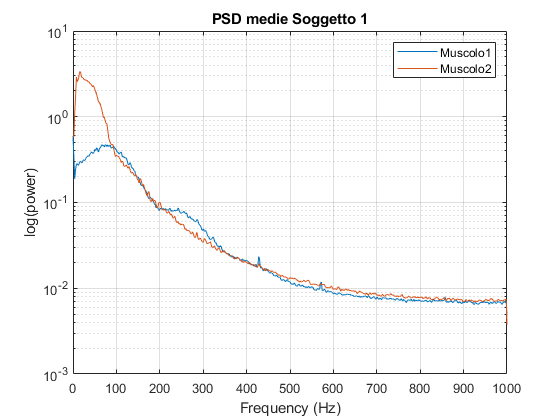

figure(1)   
semilogy(f1,Subject1_Pxxs(1,:),f1,Subject1_Pxxs(2,:));
xlabel('Frequency (Hz)');
ylabel('log(power)');
title('PSD medie Soggetto 1');
legend( 'Muscolo1', 'Muscolo2');
grid on;

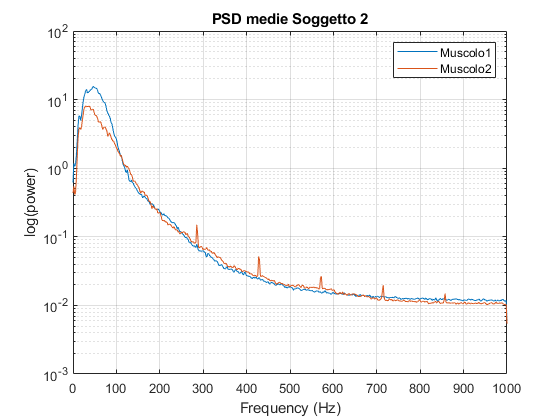


figure(2) 
semilogy(f2,Subject2_Pxxs(1,:),f2,Subject2_Pxxs(2,:));
xlabel('Frequency (Hz)');
ylabel('log(power)');
title('PSD medie Soggetto 2');
legend( 'Muscolo1', 'Muscolo2');
grid on;

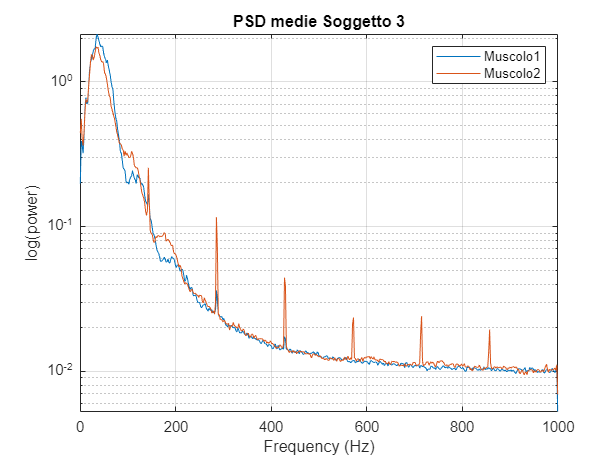


figure(3)   
semilogy(f3,Subject3_Pxxs(1,:),f3,Subject3_Pxxs(2,:));
xlabel('Frequency (Hz)');
ylabel('log(power)');
title('PSD medie Soggetto 3');
legend( 'Muscolo1', 'Muscolo2');
grid on;

Creiamo delle cell che ci aiuteranno nello svolgimento dell'obbiettivo 5 e per i plot delle attivazioni nell' obbiettivo 4

% Creiamo una cell con gli inviluppi dei muscoli 1 nei 3 soggetti nelle prime 3
% colonne e con gli inviluppi dei muscoli 2 dei 3 soggetti nelle ultime 3
% colonne.
Envelope_norm_tot = [Envelope1_norm(:,1), Envelope2_norm(:,1), Envelope3_norm(:,1)...
                    ,Envelope1_norm(:,2), Envelope2_norm(:,2), Envelope3_norm(:,2)];


Obbiettivo 4: ricerca delle attivazioni per ogni soggetto per ogni prova

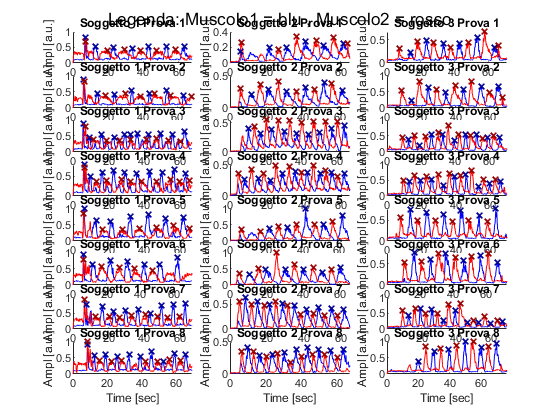

Soggetto1_activations = detect_activation(Envelope1_norm,1);
Soggetto2_activations = detect_activation(Envelope2_norm,0.9);
Soggetto3_activations = detect_activation(Envelope3_norm,0.4);

% Creo una cell che contiene i valori di attivazione del muscolo 1 dei 3
% soggetti e poi i valori di attivazioni del muscolo 2 nei 3 soggetti
VAL_activation = [Soggetto1_activations(:,1), Soggetto2_activations(:,1), Soggetto3_activations(:,1)...
                 ,Soggetto1_activations(:,3), Soggetto2_activations(:,3), Soggetto3_activations(:,3)];

% Creo una cell che contiene le posizioni di attivazione del muscolo 1 dei 3
% soggetti e poi le posizioni di attivazioni del muscolo 2 nei 3 soggetti
POS_activations = [Soggetto1_activations(:,2), Soggetto2_activations(:,2), Soggetto3_activations(:,2)...
                  ,Soggetto1_activations(:,4), Soggetto2_activations(:,4), Soggetto3_activations(:,4)];

% NOTA: Le ultime 2 cell sono state create per organizzare i dati. Si tratta di Cell 8x6 dove le righe rappresentano le prove e
% le colonne rappresentano i muscoli 1 dei 3 soggetti e i muscoli 2 dei 3 soggetti.


% Visualizziamo tutti i picchi trovati chiamando la funzione apposita Plot_activations() priva di output: 
Plot_activations(emg_data ,Envelope_norm_tot, VAL_activation, POS_activations, N_soggetti, N_prove);

Obbiettivo 5 : Visualizzazione delle singole attivazioni nelle 4 condizioni

Chiamando la funzione Data_Division() si ottengono due cell contenenti le finestre medie di attivazione e la stessa chiamata si occupa dei plot di tutte le finestre.

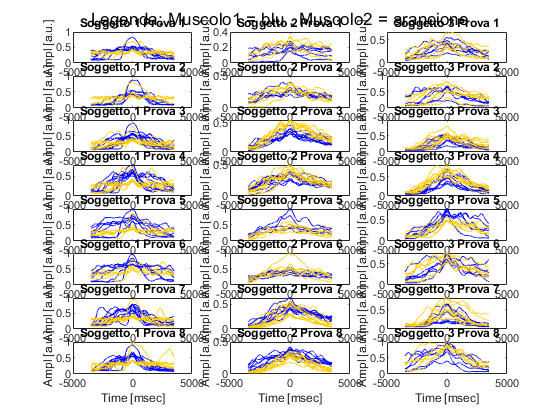

% Le cell che vengono ritornate sono riferite al muscolo 1 e 2, inoltre hanno come colonne i 3 soggetti e come
% righe le 8 prove. 
% Da notare che per disattivare i grafici è sufficiente scegliere come ultimo input '0' e per attivarli '1'.

[Windows_cell_M1, Windows_cell_M2] = Data_division(POS_activations, Envelope_norm_tot, N_prove, N_soggetti, 1);

Obbiettivo 6: Calcolare e visualizzare la durata di attivazione media per ogni soggetto e per ogni prova

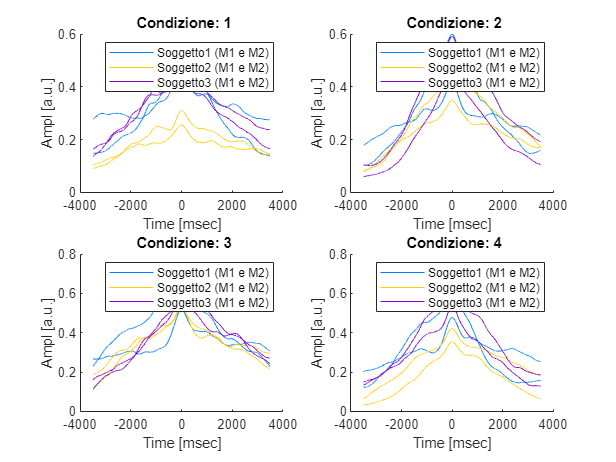

% Con una sola chiamata della funzione Windows_mean() vengono calcolate le
% finestre di attivazioni medie per ogni soggetto e condizione. Tali
% risultati sono salvati nelle due cell in uscita alla funzione e stampate.
% Anche in questo caso per disattivare i grafici è sufficiente scegliere come ultimo input '0' e per attivarli '1'.

[windows_mean_cell_M1, windows_mean_cell_M2] = Windows_mean(Windows_cell_M1, Windows_cell_M2, N_prove, N_soggetti, 1);

Chiamando la funzione evaluate_fwhm si ottiene come output tre Cell contenenti i valori di Full Width at Half Maximum (fwhm)

%calcoliamo la durata di attivazione nelle 8 prove delle 4 condizioni diverse : per ogni soggetto
%nella prima colonna avremo la durata (in millisecondi) dell'attivazione
%nelle 8 condzione per il primo muscolo, nella seconda colonna il secondo
%muscolo

[FWHM_S1, FWHM_S2 , FWHM_S3] = evaluate_fwhm(Windows_cell_M1,Windows_cell_M2);

Obiettivo 7

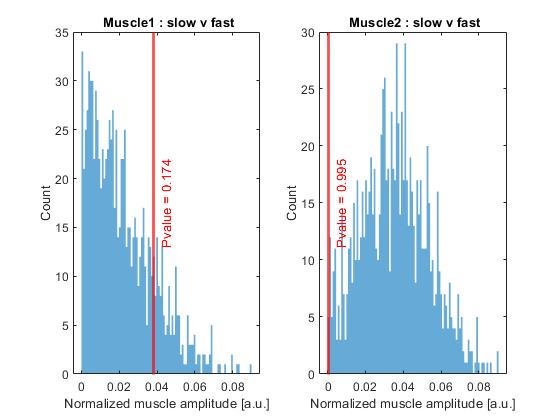

%Abbiamo scelto di svolgere il test confrontando le ampiezze dei picchi.
%Per comodità abbiamo creato due funzioni per i due test diversi
%Il test 1 sarà tra movimenti lenti e veloci,il test 2 tra movimenti
%piccoli e grandi
%Otteniamo i vettori randomici e salviamo in N1 e M1 il numero di volte in cui T_rand_M1 > Tobs_M1
%per i due test , in N2 e M2 il numero di volte in cui T_rand_M2 > Tobs_M2
%Plottiamo i risultati ottenuti
% Anche in questo caso per disattivare i grafici è sufficiente scegliere come ultimo input '0' e per attivarli '1'.


[Vettore_rand_M1_test1 , Vettore_rand_M2_test1, P_value_test1_M1, P_value_test1_M2, Tob_M1_test1, Tob_M2_test1] = permutation_test_1( Soggetto1_activations,Soggetto2_activations,Soggetto3_activations ,1);

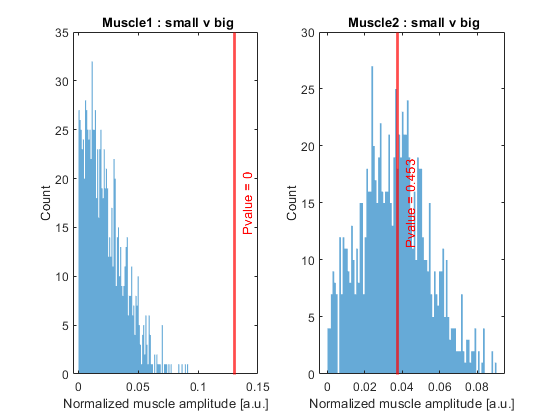

[Vettore_rand_M1_test2, Vettore_rand_M2_test2, P_value_test2_M1, P_value_test2_M2, Tob_M1_test2, Tob_M2_test2 ] = permutation_test_2( Soggetto1_activations,Soggetto2_activations,Soggetto3_activations ,1);

# **FUNZIONI**

## 1) get_envelope()

## Funzione che calcola l' inviluppo dei dati forniti.

function [Envelope_cell] = get_envelope(data)
        
% per ottenere l'inviluppo dobbiamo prima filtrare il segnale con un
% filtro passabanda, in seguito rettificarlo (calcolandone il valore
% assoluto) e infine filtrarlo con un passabasso.
% Definiamo quindi i seguenti valori (abbiamo usato i valori riportati
% nelle slide della prof Casadio):
    
fs = 2000; % Frequenza di campionamneto
    
wn_min_bp = 30/(fs/2);  % Limite inferiore (in frequenza) per il filtro passabanda normalizzata alla Frequenza di Nyquist  
wn_max_bp = 300/(fs/2); % Limite superiore (in frequenza) per il filtro passabanda normalizzata alla Frequenza di Nyquist 
order_bp = 3;           % Ordine del filtro passabanda

wn_lp = 2/(fs/2);       % Frequenza limite per il filtro passabasso normalizzata alla Frequenza di Nyquist   (4)
order_lp = 3;           % Ordine del filtro passabasso
    
% Otteniamo quindi i coefficienti per i due filtri
[b_bp,a_bp] = butter(order_bp,[wn_min_bp wn_max_bp],'bandpass');
[b_lp,a_lp] = butter(order_lp,wn_lp,'low');
    
% Pre-allochiamo la struttura che andremo a ritornare: nella prima
% colonna avremo le matrici contenenti gli inviluppi del muscolo 1,
% nella seconda quelli del muscolo 2
Envelope_cell = cell(size(data,1),2);
    
for subject_index = 1:size(data,1)
        
    % Estraiamo volta per volta la matrice di ogni rispettiva prova
    soggetto_test = data{subject_index,1};
        
    % Salviamo i valori dei singoli muscoli ignorando la prima colonna
    % (è il tempo)
        
    Muscle1 = soggetto_test(:,2);
    Muscle2 = soggetto_test(:,3);
        
    % Eseguiamo il filtraggio: prima applichiamo un passabanda, poi
    % rettifichiamo e infine applichiamo un passabasso
        
    Muscle1_filtered = filter(b_bp, a_bp, Muscle1);
    Muscle2_filtered = filter(b_bp, a_bp, Muscle2);
        
    Muscle1_rect = abs(Muscle1_filtered);
    Muscle2_rect = abs(Muscle2_filtered);
        
    %Final_Muscle1_filtered = lowpass(Muscle1_rect,4/2000);
    %Final_Muscle2_filtered = lowpass(Muscle2_rect,4/2000);
        
    Final_Muscle1_filtered = filter(b_lp, a_lp, Muscle1_rect);
    Final_Muscle2_filtered = filter(b_lp, a_lp, Muscle2_rect);

    % Riempiamo la struttura che andremo a tornare con i rispettivi
    % valori di inviluppo per ogni muscolo : nella prima
    % colonna avremo le matrici contenenti gli inviluppi del muscolo 1,
    % nella seconda quelli del muscolo 2
          
    Envelope_cell{subject_index,1} = Final_Muscle1_filtered;
    Envelope_cell{subject_index,2} = Final_Muscle2_filtered;
    
end % del for
end % della funzione

## 2) data_normalization()

## Funzione che calcola il valore massimo dello spettro in un test che riguarda sia il muscolo 1 che il muscolo 2 partendo dall' inviluppo.

function data = data_normalization(data)
    
% pre-allochiamo due matrici che conterranno i massimi di ogni prova per
% ciascun muscolo
Muscolo1_Maxs = zeros(size(data,1),1);
Muscolo2_Maxs = zeros(size(data,1),1);

for muscle_index = 1:size(data,1)
        
     % otteniamo i valori della singola prova per ogni muscolo
     Soggetto_test1=data{muscle_index,1};
     Soggetto_test2=data{muscle_index,2};

     % troviamo i massimi
     Muscolo1_Maxs(muscle_index,:)=max(Soggetto_test1);
     Muscolo2_Maxs(muscle_index,:)=max(Soggetto_test2);
           
end
    
%troviamo il massimo assoluto per ogni muscolo come massimo dei massimi
Muscolo1_Max=max(Muscolo1_Maxs);
Muscolo2_Max=max(Muscolo2_Maxs);
    
for envelope_index=1:size(data,1)
        
     %consideriamo la singola prova per ciascun muscolo e la andiamo a
     %normalizzare dividendola per il massimo del singolo muscolo
        
     Envelope_test1 = data{envelope_index,1};
     Envelope_test2 = data{envelope_index,2};
        
     Envelope_test1 = Envelope_test1/Muscolo1_Max;
     Envelope_test2 = Envelope_test2/Muscolo2_Max;
        
     % %Riempiamo la struttura che andremo a tornare con i rispettivi
     % valori di inviluppo normalizzati per ogni muscolo : nella prima
     % colonna avremo le matrici contenenti gli inviluppi del muscolo 1,
     % nella seconda quelli del muscolo 2 
        
     data{envelope_index,1} = Envelope_test1;
     data{envelope_index,2} = Envelope_test2;
end % del for
    
end % della funzione       

## 3) compute_Pxx()

## Funzione che ritorna gli spettri.

function [Muscles_Pxx,f1] = compute_Pxx(data)
 
%scegliamo il numero di campioni che utilizzeremo per calcolre la fft
nfft = 1024;
    
% Pre-allochiamo la matrice che andremo a tornare: ogni riga conterrà
% la PSD media per il singolo muscolo (riga 1 = muscolo 1, riga 2 =
% muscolo 2)
Muscles_Pxx = zeros(2,nfft/2+1);
    
% Pre-allochiamo due matrici che conterranno le PSD dei muscoli per ogni
% singola prova
Muscles_1_Pxxs = zeros(nfft/2+1,size(data,1));
Muscles_2_Pxxs = zeros(nfft/2+1,size(data,1));
    
for muscle_index = 1:size(data,1)
         
    % Otteniamo i valori della singola prova
    soggetto_test = data{muscle_index,1};
        
    % Dividiamo i valori nei due muscoli ignorando la prima colonna
    % (è il tempo)
    Muscle1 = soggetto_test(:,2);
    Muscle2 = soggetto_test(:,3);
            
    % Calcoliamo le PSD
    [Muscles_1_Pxxs(:,muscle_index),f1] = pwelch(Muscle1,hamming(1000),500,nfft,2000);
    [Muscles_2_Pxxs(:,muscle_index),~] = pwelch(Muscle2,hamming(1000),500,nfft,2000);
    
end % del for

% Calcoliamo le PSD medie   
Muscle1_mean_Pxx = mean(Muscles_1_Pxxs,2);
Muscle2_mean_Pxx = mean(Muscles_2_Pxxs,2);

% Riempiamo la matrice che andremo a ritornare
Muscles_Pxx(1,:) = Muscle1_mean_Pxx;
Muscles_Pxx(2,:) = Muscle2_mean_Pxx;

end % of function

## 4)  Soggetto_activations()

## Funzione che calcola le attivazioni e le loro posizioni.

function Soggetto_activations = detect_activation(data,multiplier)

% pre-allochiamo la struttura che andremo a ritornare : le prime due colonne
% conterranno i picchi e le posizioni di tali picchi per il muscolo 1, le
% ultime due per il muscolo 2

Soggetto_activations=cell(size(data,1),4);

for test_index=1:size(data,1)
     
    % calcolo della soglia per la singola prova per i due muscoli 
    subj_test1 = data{test_index,1};
    media = mean(subj_test1);
    std = sqrt(var(subj_test1));
    thr1 = media + multiplier * std;
     
    subj_test2=data{test_index,2};
    media = mean(subj_test2);
    std = sqrt(var(subj_test2));
    thr2 = media + multiplier * std;
     
    % Andiamo a trovare le attivazioni : per evitare di trovare picchi che
    % non siano attivazioni, andiamo a impostare un valore minimo di
    % distanza tra le attivazioni
    [Soggetto_activations{test_index,1},Soggetto_activations{test_index,2}] = findpeaks(subj_test1,'MinPeakHeight',thr1,"MinPeakDistance",7000);
    [Soggetto_activations{test_index,3},Soggetto_activations{test_index,4}] = findpeaks(subj_test2,'MinPeakHeight',thr2,"MinPeakDistance",8500);
    
    
    % Questa parte di codice serve per mostrare come non sia stato possibile
    % scegliere dei parametri per la funzione data_activation() così da trovare
    % tutti i picchi e ignorando i falsi picchi di attivazione individuati
    % SOLO in alcune prove del muscolo 2 del soggetto 1.
    
    % Per ovviare al problema abbiamo eliminato i picchi troppo
    % vicini all' inizio della registrazione imponendo una soglia di 4000
    % campioni che corrispondono a 2 secondi.
    
 Min_distance_threshold =  4000;
 
    if Soggetto_activations{test_index,2}(1,1) < Min_distance_threshold
          
          Soggetto_activations{test_index,2} = Soggetto_activations{test_index,2}(2:numel(Soggetto_activations{test_index,2}),1);
          Soggetto_activations{test_index,1} = Soggetto_activations{test_index,1}(2:numel(Soggetto_activations{test_index,1}),1);
    end
    
    if Soggetto_activations{test_index,4}(1,1) < Min_distance_threshold
        
        Soggetto_activations{test_index,4} = Soggetto_activations{test_index,4}(2:numel(Soggetto_activations{test_index,4}),1);
        Soggetto_activations{test_index,3} = Soggetto_activations{test_index,3}(2:numel(Soggetto_activations{test_index,3}),1);
    end
    
end % del for

end % della funzione

## 5) Plot_activations()

##  Funzione con il solo scopo di plottare gli inviluppi normalizzati e i rispettivi picchi di attivazione.

function Plot_activations(emg_data, Envelope_norm_tot, VAL_activation, POS_activations, N_soggetti, N_prove)

posizione = 1;% contatore che ci servirà per plottare tutti i grafici in un unico subplot
for contatore_prove = 1:N_prove     
         
      for contatore_soggetto = 1:N_soggetti 
          
          %definiamo il vettore del tempo
           time = emg_data{contatore_prove, contatore_soggetto}(:,1);
           
           %plottiamo gli inviluppi
           subplot( N_prove, N_soggetti, posizione )
           hold on
           plot(time, Envelope_norm_tot{contatore_prove, contatore_soggetto} ,"Color",'b');
           plot(time, Envelope_norm_tot{contatore_prove, contatore_soggetto + 3} ,"Color",'r');
          
           %plottiamo i picchi sull'asse del tempo, così da poterli
           %sovrapporre al grafico dell'inviluppo
                  x_M1 = time(POS_activations{contatore_prove, contatore_soggetto});     
                  plot(x_M1, VAL_activation{contatore_prove, contatore_soggetto},"x",'color',[0, 0, 0.6],"LineWidth",1.2);
      
                  x_M2 = time(POS_activations{contatore_prove, contatore_soggetto + 3}); 
                  plot(x_M2, VAL_activation{contatore_prove, contatore_soggetto + 3},"x",'color',[0.6, 0, 0],"LineWidth",1.2);
                  
           hold off
           sgtitle("Legenda: Muscolo1 = blu , Muscolo2 = rosso")
           title(['Soggetto ' num2str( contatore_soggetto ) ' Prova '  num2str( contatore_prove )])
           xlabel('Time [sec]') 
           ylabel('Ampl [a.u.]')
           posizione = posizione + 1;
           
      end    
      
end % del for esterno

end % of function

## 6) Data_division()

## Funzione che crea e grafica le Cell (rispettive ai muscoli 1 e 2) contenenti le finestre di attivazioni  suddivise per prova e soggetto.

function [windows_cell_M1, windows_cell_M2] = Data_division (data, Env_tot, N_prove, N_soggetti, grafici_ON)
% data contiene le posizioni delle attivazioni del M1 nei 3 soggetti e
% poi le posizioni dei M2 nei 3 soggetti
     
% Env_tot contiene gli inviluppi dei M1 dei te soggetti nelle prime 3
% colonne e gli inviluppi dei M2 dei 3 soggetti nelle ultime 3 colonne
     
     
window_length = 7001;   % fisso la lunghezza della finestra a 7001 msec =~ 0.7 sec (come nell' helpdoc)
windows_cell_M1 = cell(N_prove, N_soggetti); % Le colonne sono dedicate ai soggetti e le righe sono dedicate alle prove.
windows_cell_M2 = cell(N_prove, N_soggetti); % Ogni cella conterrà una matrice le cui righe saranno le finestre centrate
                                             % nelle posizioni in cui si hanno picchi di attivazione.
                                             
     
for contatore_soggetto = 1:N_soggetti     
      pos_M1 = data(:, contatore_soggetto);                   % in questi 4 comandi seleziono le colonne delle cell in ingresso
      pos_M2 = data(:, contatore_soggetto + N_soggetti);      % che sono riferite alle posizioni dei picchi e agli inviluppi dei 
      Env_M1 = Env_tot(:, contatore_soggetto);                % due muscoli di un solo soggetto in tutte le prove.
      Env_M2 = Env_tot(:, contatore_soggetto+ N_soggetti);
          
      for contatore_prove = 1:N_prove    % for delle singole prove
                 
            pos_M1_temp = pos_M1{contatore_prove, 1};   % posizione picchi di M1 della singola prova di un solo soggetto.
            pos_M2_temp = pos_M2{contatore_prove, 1};   % stesso comando riferito però a M2.    
            env_M1_temp = Env_M1{contatore_prove, 1};   % inviluppo di M1 riferito alla singola prova
            env_M2_temp = Env_M2{contatore_prove, 1};   % inviluppo di M2 riferito alla singola prova
            
            N_attivazioni_M1 = numel(pos_M1_temp);  % Salva il numero di attivazioni contando il numero delle posizioni dei
            N_attivazioni_M2 = numel(pos_M2_temp);  % picchi che coincide con il numero di picchi di attivazioni.

            
            % Questo blocco di if serve a non considerare picchi troppo
            % vicini alla fine della registrazione, giacchè una finestra
            % centrata in tali picchi eccederebbe il termine della
            % registrazione
            % In particolare abbiamo notato ciò solamente in un'attivazione
            % del muscolo2 nel primo soggetto
     
             
            if (pos_M1_temp(N_attivazioni_M1) + (window_length-1)/2) > numel(env_M1_temp)
                N_attivazioni_M1 = N_attivazioni_M1 - 1;
            end
            if (pos_M2_temp(N_attivazioni_M2) + (window_length-1)/2) > numel(env_M2_temp)
                N_attivazioni_M2 = N_attivazioni_M2 - 1;
            end
            
            
            windows_matrix_M1 = zeros(N_attivazioni_M1, window_length); % matrice che conterrà le finestre e cehe poi verrà salvata nella cell corrispondente
            windows_matrix_M2 = zeros(N_attivazioni_M2, window_length); 
            
            % Significa che windows_matrix_M1 e windows_matrix_M2 conterranno (lungo le righe) 
            % le finestre di attivazione rispettivamente di M1 e di M2.
                 
            for contatore_attivazioni_M1 = 1:N_attivazioni_M1 
            
                   window_M1 = env_M1_temp( pos_M1_temp(contatore_attivazioni_M1)-(window_length-1)/2 : pos_M1_temp(contatore_attivazioni_M1)+(window_length-1)/2 );
                   windows_matrix_M1(contatore_attivazioni_M1, :) = (window_M1)' ;
            end
            
            for contatore_attivazioni_M2 = 1:N_attivazioni_M2 
                   window_M2 = env_M2_temp( pos_M2_temp(contatore_attivazioni_M2)-(window_length-1)/2 : pos_M2_temp(contatore_attivazioni_M2)+(window_length-1)/2 );
                   windows_matrix_M2( contatore_attivazioni_M2, :) = (window_M2)' ;
                 
            end % for numero 3
                 
            windows_cell_M1{contatore_prove, contatore_soggetto} = windows_matrix_M1; 
            windows_cell_M2{contatore_prove, contatore_soggetto} = windows_matrix_M2; 
                 
       end % for numero 2
           
end % for numero 1




% Parte della funzione che genera i grafici di tutte le finestre di attivazione se grafici_ON = 1
if grafici_ON
figure
window_length = 7001;  % manteniamo la stessa lunghezza delle finestre
x = -(window_length-1)/2:(window_length-1)/2;
posizione = 1;
for row = 1:size(windows_cell_M1,1)
      for column = 1:size(windows_cell_M1,2)
          
          subplot( size(windows_cell_M1,1), size(windows_cell_M1,2), posizione )
          
          plot(x, windows_cell_M1{row, column},"Color",'b')
          hold on
          plot(x, windows_cell_M2{row, column},"Color",[1, 0.8, 0])
          hold off
          title(['Soggetto ' num2str( column ) ' Prova '  num2str( row )])
          xlabel('Time [msec]') 
          ylabel('Ampl [a.u.]')
          sgtitle("Legenda: Muscolo1 = blu , Muscolo2 = arancione")

          
          posizione = posizione + 1;
      end
end

end % dell'if
    
end % della funzione

## 7) Windows_mean()

## Funzione che crea e grafica due Cell corrispondenti ai muscoli 1 e 2. Esse contengono la finestra media in base al soggetto (1,2,3) e alla condizione (1,2,3,4). 

function [windows_mean_cell_M1, windows_mean_cell_M2] = Windows_mean(Windows_cell_M1, Windows_cell_M2, N_prove, N_soggetti, grafici_ON)
% Calcolo della finestra media
windows_mean_cell_M1 = cell(N_prove/2, N_soggetti);   % Costruiamo le cell che la funzione da in output
windows_mean_cell_M2 = cell(N_prove/2, N_soggetti);   % basandoci sul numero di soggetti e di prove.

% Usiamo un doppio for per spostarci lungo le righe e colonne.
% La funzione cat è particolarmente comoda per concatenare le cell delle prove
% effettuate nelle stesse condizioni per ogni soggetto e per ogni muscolo.
% Infine quando ogni cell contiene solo le finestre volute si effettua la
% media con la funzione mean()

for column = 1:size(windows_mean_cell_M1, 2)
      for row = 1: size(windows_mean_cell_M1, 1)
          windows_mean_cell_M1{row, column} = mean(  cat( 1, Windows_cell_M1{(2*row)-1, column}, Windows_cell_M1{2*row, column})   );
          windows_mean_cell_M2{row, column} = mean(  cat( 1, Windows_cell_M2{(2*row)-1, column}, Windows_cell_M2{2*row, column})   );
      end
end % le due cell che si ottengono contengono le finestre medie per condizione e soggetto, rispettivamente per il M1 e M2


if grafici_ON
    
% plot: il corretto colore delle curve lo si ha solo con un numero di soggetti pari a 3
figure
window_length = 7001;  % Si sceglie una lunghezza di finestra corrispondente a quella scelta nella funzione
x = -(window_length-1)/2:(window_length-1)/2;
numero_condizioni = size( windows_mean_cell_M1, 1);

for condizione = 1:numero_condizioni
      subplot(2, 2, condizione )  % suppongo che le condizioni siano sempre 4 e creo un subplot di 4 elementi grafici
      hold on
      for soggetto = 1:N_soggetti
          % per impostare il colore in modo da seguire le indicazioni dell'HelpDoc
          if soggetto == 1
                color = [0, 0.5, 1]; % azzurro soggetto 1
          elseif soggetto == 2
                color = [1, 0.8, 0]; % arancione soggetto 2 
          else
                color = [0.5, 0, 0.8]; % viola soggetto 3
          end
          plot(x, windows_mean_cell_M1{condizione, soggetto}, "Color", color)
          plot(x, windows_mean_cell_M2{condizione, soggetto}, "Color", color)
          

      end
      title([' Condizione: '  num2str( condizione )])
      xlabel('Time [msec]') 
      ylabel('Ampl [a.u.]')
      legend('Soggetto1 (M1 e M2)','','Soggetto2 (M1 e M2)','','Soggetto3 (M1 e M2)','')
      hold off
    
end % del for
end % dell' if


end % della funzione

## 8) evaluate_fwhm()

## Funzione che calcola fwhm.

function [FWHM_S1 , FWHM_S2 , FWHM_S3] = evaluate_fwhm(data1 , data2 )

%funzione che ci permetterà di calcolare la full_width_at_half_maximum
%(FWHM) per i tre soggetti , così da poter calcolare la durata di ogni
%attivazione : tale durata sarà infatti la distanza tra i due punti
%secanti, ergo la dimensione delle singole FWHM


%pre-allochiamo le matrici che conterranno le dimensioni delle varie FWHM

FWHM_S1 = cell(size(data1,1),2); 
FWHM_S2 = cell(size(data1,1),2); 
FWHM_S3 = cell(size(data1,1),2); 

for test_index = 1:size(data1,1)
    
 %dividiamo le attivazioni medie per muscolo e soggetto 
    
test1S1 = mean(data1{test_index,1});
test2S1 = mean(data2{test_index,1});

test1S2 = mean(data1{test_index,2});
test2S2 = mean(data2{test_index,2});

test1S3 = mean(data1{test_index,3});
test2S3 = mean(data2{test_index,3});

%calcoliamo l'FWHM: troviamo la metà dell'ampiezza massima , troviamo i valori delle attivazioni medie maggiori o
%uguali di tale valore e ne calcoliamo la durata, ergo la dimensione.

Half_max1S1 = (max(test1S1))/2;
Half_max_index1S1 = find(test1S1 >= Half_max1S1);
FWHM_S1{test_index,1} = numel(test1S1(:,Half_max_index1S1(1):Half_max_index1S1(size(Half_max_index1S1,2))));

Half_max2S1 = (max(test2S1))/2;
Half_max_index2S1 = find(test2S1 >= Half_max2S1);
FWHM_S1{test_index,2} = numel(test1S2(:,Half_max_index2S1(1):Half_max_index2S1(size(Half_max_index2S1,2))));



Half_max1S2 = (max(test1S2))/2;
Half_max_index1S2 = find(test1S2 >= Half_max1S2);
FWHM_S2{test_index,1} = numel(test1S2(:,Half_max_index1S2(1):Half_max_index1S2(size(Half_max_index1S2,2))));

Half_max2S2 = (max(test2S2))/2;
Half_max_index2S2 = find(test2S2 >= Half_max2S2);
FWHM_S2 {test_index,2} = numel(test2S2(:,Half_max_index2S2(1):Half_max_index2S2(size(Half_max_index2S2,2))));



Half_max1S3 = (max(test1S3))/2;
Half_max_index1S3 = find(test1S3 >= Half_max1S3);
FWHM_S3{test_index,1} = numel(test1S3(:,Half_max_index1S3(1):Half_max_index1S3(size(Half_max_index1S3,2))));

Half_max2S3 = (max(test2S3))/2;
Half_max_index2S3 = find(test2S3 >= Half_max2S3);
FWHM_S3{test_index,2} = numel(test2S3(:,Half_max_index2S3(1):Half_max_index2S3(size(Half_max_index2S3,2))));

end % del ciclo   

end% of function

## 9) Permutation_Test_1() : svolgiamo il test tra movimenti lenti e veloci 


function [Vettore_rand_M1_test1 , Vettore_rand_M2_test1 , P_value_M1 , P_value_M2 , Tobs_M1 , Tobs_M2] = permutation_test_1(data1 , data2 , data3 , grafici_ON)
   
% svolgiamo il permutation test tra movimenti lenti e veloci 

%STEP1
%dividiamo i dati in movimenti piccoli/grandi per i due muscoli 

Vettore_lenti_M1 = [data1{1,1} ;data1{2,1} ; data1{5,1} ;  data1{6,1} ;data2{1,1} ;data2{2,1} ; data2{5,1} ;  data2{6,1}  ; data3{1,1} ;data3{2,1} ; data3{5,1} ;  data3{6,1} ];

Vettore_veloci_M1 = [data1{3,1} ;data1{4,1} ; data1{7,1} ;  data1{8,1} ;data2{3,1} ;data2{4,1} ; data2{7,1} ;  data2{8,1}  ; data3{3,1} ;data3{4,1} ; data3{7,1} ;  data3{8,1} ];

Vettore_lenti_M2 = [data1{1,3} ;data1{2,3} ; data1{5,3} ;  data1{6,3} ;data2{1,3} ;data2{2,3} ; data2{5,3} ;  data2{6,3}  ; data3{1,3} ;data3{2,3} ; data3{5,3} ;  data3{6,3} ];

Vettore_veloci_M2 = [data1{3,3} ;data1{4,3} ; data1{7,3} ;  data1{8,3} ;data2{3,3} ;data2{4,3} ; data2{7,3} ;  data2{8,3}  ; data3{3,3} ;data3{4,3} ; data3{7,3} ;  data3{8,3} ];

% creiamo la variabile Tobs per i due muscoli

Tobs_M1 = abs(mean(Vettore_lenti_M1) - mean(Vettore_veloci_M1));
Tobs_M2 = abs(mean(Vettore_lenti_M2) - mean(Vettore_veloci_M2));

% STEP2

% Definiamo 4 contatori:

N = 1;% ci servirà per reiterare lo step 2 tramite un while
P_counter_1 = 0;% ci servirà per vedere quante volte T_rand_M1 > Tobs_M1 
P_counter_2 = 0;% ci servirà per vedere quante volte T_rand_M2 > Tobs_M2
N_LOOP = 1000;% il numero di iterazioni del while

Trand_values_M1 = zeros(N_LOOP,1);
Trand_values_M2 = zeros(N_LOOP,1);
 

while(N<N_LOOP)
      %creiamo i vettori randomici che poi andremo a plottare nell'istogramma

      Vettore_rand_M1_test1 = [Vettore_lenti_M1 ; Vettore_veloci_M1];
      Vettore_rand_M2_test1 = [Vettore_lenti_M2 ; Vettore_veloci_M2];
 
      Vettore_rand_M1_test1 = Vettore_rand_M1_test1(randperm(length(Vettore_rand_M1_test1)));
      Vettore_rand_M2_test1= Vettore_rand_M2_test1(randperm(length(Vettore_rand_M2_test1)));

      num_lenti_M1 = numel(Vettore_lenti_M1);
      num_veloci_M1= numel(Vettore_veloci_M1);

      %dividiamo i vettori randomici in 2 sottovettori per poi ottenere la
      %variabile randomica T_rand

      Vettore_rand_M1_1 = Vettore_rand_M1_test1(1:num_lenti_M1,:);
      Vettore_rand_M1_2 = Vettore_rand_M1_test1(num_lenti_M1:num_lenti_M1+num_veloci_M1,:);

      T_rand_M1 = abs(mean(Vettore_rand_M1_1) - mean(Vettore_rand_M1_2));

      num_lenti_M2 = numel(Vettore_lenti_M2);
      num_veloci_M2 = numel(Vettore_veloci_M2);

      Vettore_rand_M2_1 = Vettore_rand_M2_test1(1:num_lenti_M2,:);
      Vettore_rand_M2_2 = Vettore_rand_M1_test1(num_lenti_M2:num_lenti_M2+num_veloci_M2,:);

      T_rand_M2 = abs(mean(Vettore_rand_M2_1) - mean(Vettore_rand_M2_2));

      % Verifichiamo quante volte si ha T_rand_M1 > Tobs_M1 e T_rand_M2 > Tobs_M2

      if (T_rand_M1 > Tobs_M1)
    
            P_counter_1 = P_counter_1 + 1;
      end

      if (T_rand_M2 > Tobs_M2)
    
            P_counter_2 = P_counter_2 + 1;
      end 

      Trand_values_M1(N,1 )= T_rand_M1;
      Trand_values_M2(N,1 )= T_rand_M2;

      N=N+1;

end % del while

%calcoliamo i Pvalue
 P_value_M1 = P_counter_1/N_LOOP;
 P_value_M2 = P_counter_2/N_LOOP;
 
if  grafici_ON
 
      figure(1)

      subplot(1,2,1);
     
      pks_bins=bin_edges(Trand_values_M1,100);
      histogram(Trand_values_M1,pks_bins,"EdgeColor","none");
      hold on
      title(" Muscle1 : slow v fast")
      xline(Tobs_M1, "r",['Pvalue = ' num2str( P_value_M1 ) ],'LabelVerticalAlignment','middle','Linewidth',2);
      xlabel("Normalized muscle amplitude [a.u.]")
      ylabel("Count")
      
      hold off
      

      subplot(1,2,2);
  
      pks_bins=bin_edges(Trand_values_M2,100);
      histogram(Trand_values_M2,pks_bins,"EdgeColor","none");
      hold on
      title(" Muscle2 : slow v fast")
      xline(Tobs_M2, "r",['Pvalue = ' num2str( P_value_M2 ) ],'LabelVerticalAlignment','middle','Linewidth',2);
      xlabel("Normalized muscle amplitude [a.u.]")
      ylabel("Count")
      hold off
      
end % dell' if 

end % of function

## 10) Permutation_Test_2() : svolgiamo il test tra movimenti piccoli e grandi 

function [Vettore_rand_M1 , Vettore_rand_M2 , P_value_M1 , P_value_M2 , Tobs_M1 , Tobs_M2] = permutation_test_2(data1 , data2 , data3 , grafici_ON)
    
% svolgiamo il permutation test tra movimenti piccoli e grandi 

% STEP1
% dividiamo i dati in movimenti piccoli/grandi per i due muscoli 

Vettore_piccoli_M1 = [data1{1,1} ;data1{2,1} ; data1{3,1} ;  data1{4,1} ;data2{1,1} ;data2{2,1} ; data2{3,1} ;  data2{4,1}  ; data3{1,1} ;data3{2,1} ; data3{3,1} ;  data3{4,1} ];
 
Vettore_grandi_M1 = [data1{5,1} ;data1{6,1} ; data1{7,1} ;  data1{8,1} ;data2{5,1} ;data2{6,1} ; data2{7,1} ;  data2{8,1}  ; data3{5,1} ;data3{6,1} ; data3{7,1} ;  data3{8,1} ];

Vettore_piccoli_M2 = [data1{1,3} ;data1{2,3} ; data1{3,3} ;  data1{4,3} ;data2{1,3} ;data2{2,3} ; data2{3,3} ;  data2{4,3}  ; data3{1,3} ;data3{2,3} ; data3{3,3} ;  data3{4,3} ];

Vettore_grandi_M2 = [data1{5,3} ;data1{6,3} ; data1{7,3} ;  data1{8,3} ;data2{5,3} ;data2{6,3} ; data2{7,3} ;  data2{8,3}  ; data3{5,3} ;data3{6,3} ; data3{7,3} ;  data3{8,3} ];

% creiamo la variabile Tobs per i due muscoli

Tobs_M1 = abs(mean(Vettore_piccoli_M1) - mean(Vettore_grandi_M1));
Tobs_M2 = abs(mean(Vettore_piccoli_M2) - mean(Vettore_grandi_M2));
 
% STEP2
% Definiamo 4 contatori:

N = 1;    % ci servirà per reiterare lo step 2 tramite un while
P_counter_1 = 0;   % ci servirà per vedere quante volte T_rand_M1 > Tobs_M1 
P_counter_2 = 0;   % ci servirà per vedere quante volte T_rand_M2 > Tobs_M2
N_LOOP = 1000;%il numero di iterazioni del while

Trand_values_M1 = zeros(N_LOOP,1);
Trand_values_M2 = zeros(N_LOOP,1);

while(N<N_LOOP)
       % creiamo i vettori randomici che poi andremo a plottare nell'istogramma

       Vettore_rand_M1 = [Vettore_piccoli_M1 ; Vettore_grandi_M1];
       Vettore_rand_M2 = [Vettore_piccoli_M2 ; Vettore_grandi_M2];
 
       Vettore_rand_M1 = Vettore_rand_M1(randperm(length(Vettore_rand_M1)));
       Vettore_rand_M2 = Vettore_rand_M2(randperm(length(Vettore_rand_M2)));


       num_piccoli_M1 = numel(Vettore_piccoli_M1);
       num_grandi_M1= numel(Vettore_grandi_M1);

       % dividiamo i vettori randomici in 2 sottovettori per poi ottenere la
       % variabile randomica T_rand

       Vettore_rand_M1_1 = Vettore_rand_M1(1:num_piccoli_M1,:);
       Vettore_rand_M1_2 = Vettore_rand_M1(num_piccoli_M1:num_piccoli_M1+num_grandi_M1,:);

       T_rand_M1 = abs(mean(Vettore_rand_M1_1) - mean(Vettore_rand_M1_2));

       num_piccoli_M2 = numel(Vettore_piccoli_M2);
       num_grandi_M2 = numel(Vettore_grandi_M2);

       Vettore_rand_M2_1 = Vettore_rand_M2(1:num_piccoli_M2,:);
       Vettore_rand_M2_2 = Vettore_rand_M1(num_piccoli_M2:num_piccoli_M2+num_grandi_M2,:);

       T_rand_M2 = abs(mean(Vettore_rand_M2_1) - mean(Vettore_rand_M2_2));

       % Verifichiamo quante volte si ha T_rand_M1 > Tobs_M1 e T_rand_M2 > Tobs_M2

       if (T_rand_M1 > Tobs_M1)
   
            P_counter_1 = P_counter_1 + 1;
       end

       if (T_rand_M2 > Tobs_M2)
    
            P_counter_2 = P_counter_2 + 1;     
       end

       Trand_values_M1(N,1 )= T_rand_M1;
       Trand_values_M2(N,1 )= T_rand_M2;

       N = N+1;

end % del while


 %calcoliamo i Pvalue
 
 P_value_M1 = P_counter_1/N_LOOP;
 P_value_M2 = P_counter_2/N_LOOP;

 

if  grafici_ON
 
  
      figure(2)
      subplot(1,2,1);
      
      pks_bins=bin_edges(Trand_values_M1,100);
      histogram(Trand_values_M1,pks_bins,"EdgeColor","none");
      hold on
      title(" Muscle1 : small v big")
      xline(Tobs_M1, "r",['Pvalue = ' num2str( P_value_M1 ) ],'LabelVerticalAlignment','middle','Linewidth',2);
      xlabel("Normalized muscle amplitude [a.u.]")
      ylabel("Count")
      hold off

      subplot(1,2,2);
 
      pks_bins=bin_edges(Trand_values_M2,100);
      histogram(Trand_values_M2,pks_bins,"EdgeColor","none");
      hold on
      title(" Muscle2 : small v big")
      xline(Tobs_M2, "r",['Pvalue = ' num2str( P_value_M2 ) ],'LabelVerticalAlignment','middle','Linewidth',2);
      xlabel("Normalized muscle amplitude [a.u.]")
      ylabel("Count")
      hold off
end % del if 



end % of function

## 11) bin_edges()

## Funzione che gestisce i bins.

function data_bins=bin_edges(data,n_bins)

datamin=min(data);
datamax=max(data);
data_bins=linspace(datamin,datamax,(n_bins+1));

end